## Exercise 1

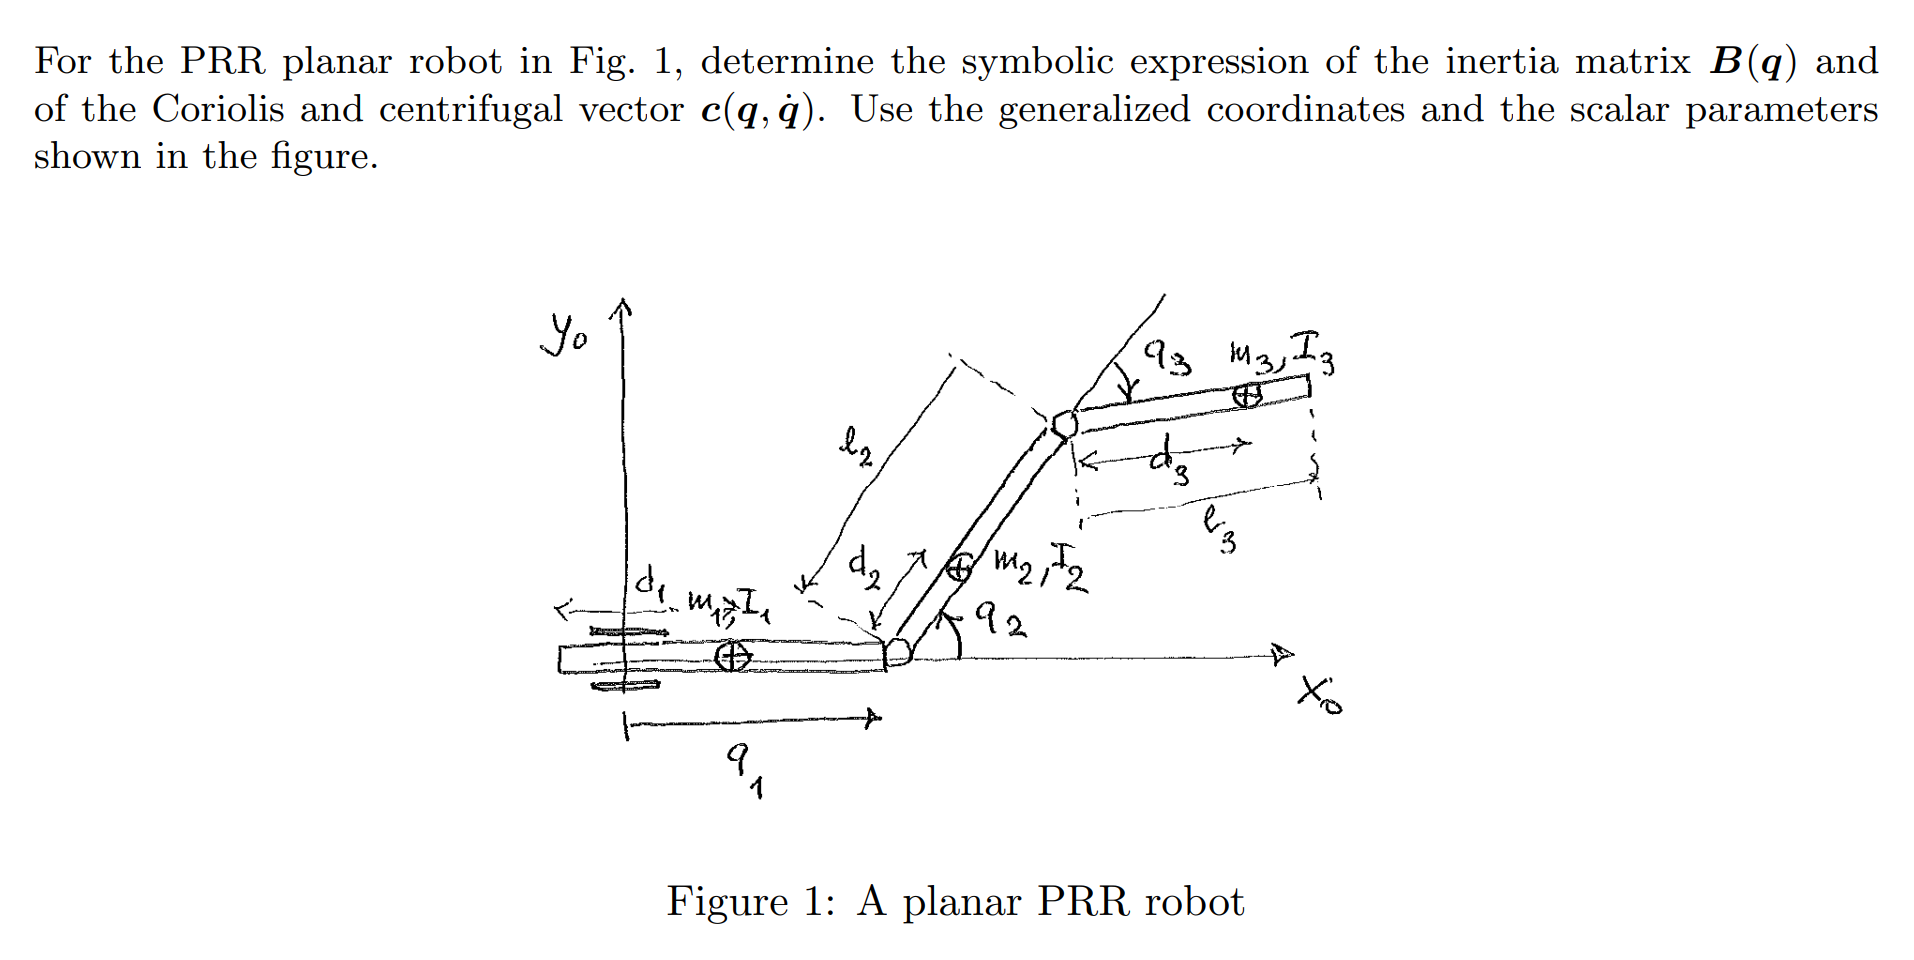

syms q1 q2 q3 dq1 dq2 dq3 real
syms m1 m2 m3 l2 l3 d2 d3 I2 I3 g0 positive

% Joint 1
T1 = 0.5*m1*dq1^2;

% Joint 2
x2 = q1 + d2*cos(q2);
y2 = d2*sin(q2);

vx2 = diff(x2,q1)*dq1+diff(x2,q2)*dq2+diff(x2,q3)*dq3;
vy2 = diff(y2,q1)*dq1+diff(y2,q2)*dq2+diff(y2,q3)*dq3;

T2_tr = 0.5*m2*[vx2 vy2]*[vx2; vy2;];
T2_rot = 0.5*I2*dq2^2;

T2 = T2_rot+T2_tr;

% Joint 3
x3 = q1 + l2*cos(q2) + d3*cos(q2+q3);
y3 = l2*sin(q2) + d3*sin(q2+q3);

vx3 = diff(x3,q1)*dq1+diff(x3,q2)*dq2+diff(x3,q3)*dq3;
vy3 = diff(y3,q1)*dq1+diff(y3,q2)*dq2+diff(y3,q3)*dq3;

T3_tr = 0.5*m3*[vx3 vy3]*[vx3; vy3;];
T3_rot = 0.5*I3*(dq2+dq3)^2;

T3 = T3_rot+T3_tr;

% Total Kinetic Energy
T = T1+T2+T3;

% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);
M13 = diff(diff(T, dq1), dq3);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);
M23 = diff(diff(T, dq2), dq3);

M31 = diff(diff(T, dq3), dq1);
M32 = diff(diff(T, dq3), dq2);
M33 = diff(diff(T, dq3), dq3);

M = [M11, M12, M13;
     M21, M22, M23;
     M31, M32, M33];

M = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\begin{array}{l} \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & -\frac{m_{3}\,\left(2\,d_{3}\,\sin\left(q_{2}+q_{3}\right)+2\,l_{2}\,\sin\left(q_{2}\right)\right)}{2}-\sigma_{3} & \sigma_{2}\\ -m_{3}\,\left(d_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\right)-\sigma_{3} & m_{2}\,{d_{2}}^{2}+m_{3}\,{d_{3}}^{2}+2\,m_{3}\,\cos\left(q_{3}\right)\,d_{3}\,l_{2}+m_{3}\,{l_{2}}^{2}+I_{2}+I_{3} & \sigma_{1}\\ \sigma_{2} & \sigma_{1} & m_{3}\,{d_{3}}^{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{3}\,{d_{3}}^{2}+l_{2}\,m_{3}\,\cos\left(q_{3}\right)\,d_{3}+I_{3}\\ \sigma_{2}=-d_{3}\,m_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{3}=d_{2}\,m_{2}\,\sin\left(q_{2}\right) \end{array}$$


% Coriolis and Centrifugal terms
q  = [q1; q2; q3;];
dq = [dq1; dq2; dq3;];


C = sym(zeros(3,3));

for i = 1:3
    for j = 1:3
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:3
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  
    end
end

c_vec = C * dq;

% disp('La matrice di Coriolis C(q,dq) è:');
% disp(C);
% 
% disp('Il vettore c(q,dq) = C(q,dq)*dq è:');
% disp(c_vec);
% 
% disp('La matrice di Coriolis C(q,dq) è:');
% disp(C);

disp('Vector c(q,dq) = C(q,dq)*dq è:');

Vector c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -{\mathrm{dq}}_{2}\,\left({\mathrm{dq}}_{2}\,\left(\frac{m_{3}\,\left(2\,d_{3}\,\cos\left(q_{2}+q_{3}\right)+2\,l_{2}\,\cos\left(q_{2}\right)\right)}{2}+d_{2}\,m_{2}\,\cos\left(q_{2}\right)\right)+d_{3}\,{\mathrm{dq}}_{3}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)\right)-d_{3}\,{\mathrm{dq}}_{3}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)\\ -d_{3}\,{\mathrm{dq}}_{3}\,l_{2}\,m_{3}\,\sin\left(q_{3}\right)\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)-d_{3}\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}\,l_{2}\,m_{3}\,\sin\left(q_{3}\right)\\ d_{3}\,{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,m_{3}\,\sin\left(q_{3}\right) \end{array}\right)$$

## Exercise 2

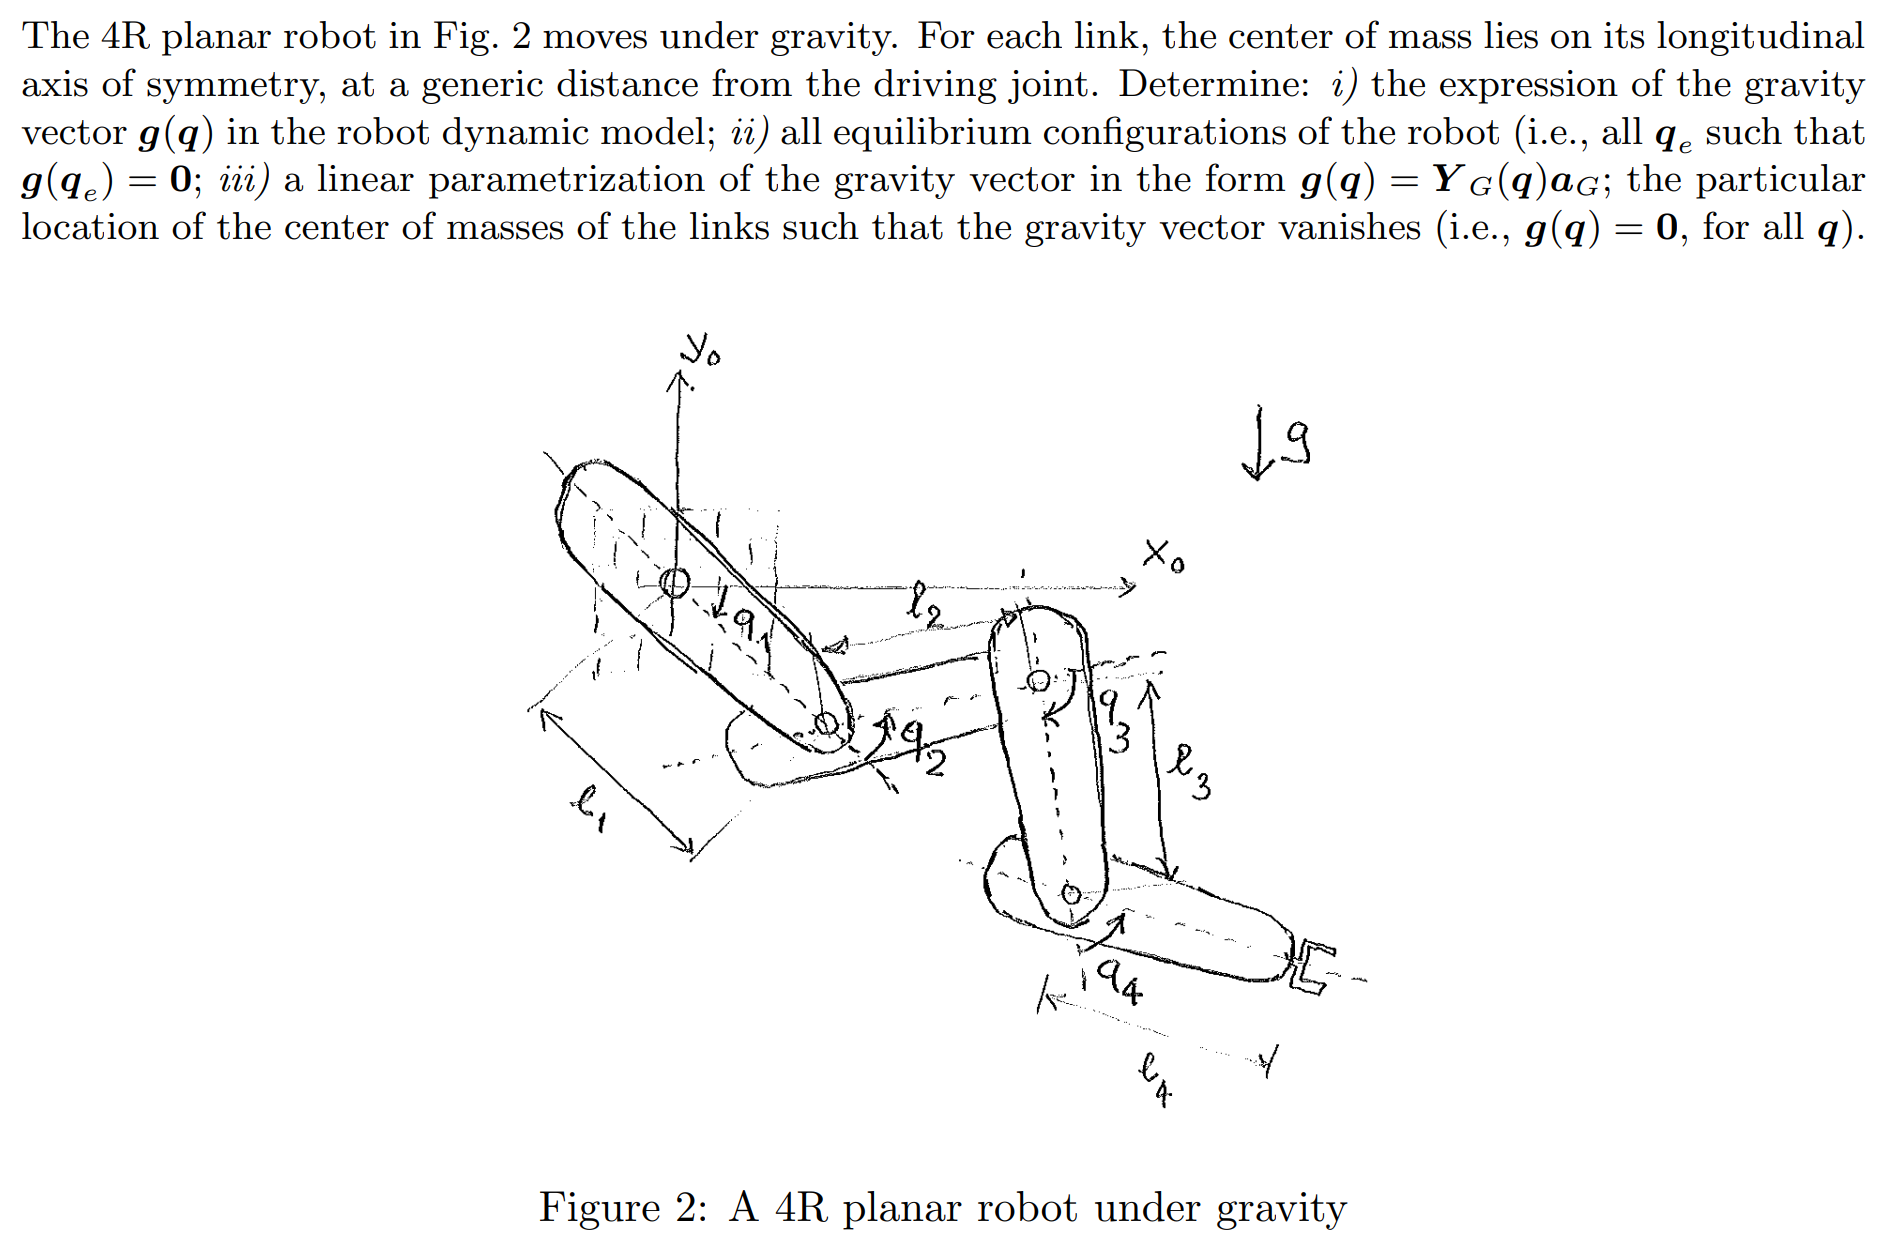

### Point 1

Gravity terms

syms m1 m2 m3 m4 g0 d1 l1 d2 l2 d3 l3 d4 l4 positive
syms q1 q2 q3 q4 dq1 dq2 dq3 dq3 real 

U1 = -m1*g0*d1*sin(q1);
U2 = -m2*g0*(l1+d2*sin(q1+q2));
U3 = -m3*g0*(l1*sin(q1)+l2*sin(q1+q2)+d3*sin(q1+q2+q3));
U4 = -m4*g0*(l1*sin(q1)+l2*sin(q1+q2)+l3*sin(q1+q2+q3)+d4*sin(q1+q2+q3+q4));

U = [U1 + U2 + U3 + U4];
g_q = [diff(U, q1); diff(U, q2); diff(U, q3); diff(U, q4)];

disp("Vector Gravity Terms: ");

Vector Gravity Terms: 


disp(g_q);

$$\begin{array}{l} \left(\begin{array}{c} -g_{0}\,m_{3}\,\left(\sigma_{1}+l_{1}\,\cos\left(q_{1}\right)+d_{3}\,\sigma_{2}\right)-g_{0}\,m_{4}\,\left(d_{4}\,\sigma_{4}+\sigma_{1}+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\sigma_{2}\right)-\sigma_{3}-d_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)\\ -g_{0}\,m_{4}\,\left(d_{4}\,\sigma_{4}+\sigma_{1}+l_{3}\,\sigma_{2}\right)-g_{0}\,m_{3}\,\left(\sigma_{1}+d_{3}\,\sigma_{2}\right)-\sigma_{3}\\ -g_{0}\,m_{4}\,\left(d_{4}\,\sigma_{4}+l_{3}\,\sigma_{2}\right)-d_{3}\,g_{0}\,m_{3}\,\sigma_{2}\\ -d_{4}\,g_{0}\,m_{4}\,\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{3}=d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right) \end{array}$$

## Exercise 3

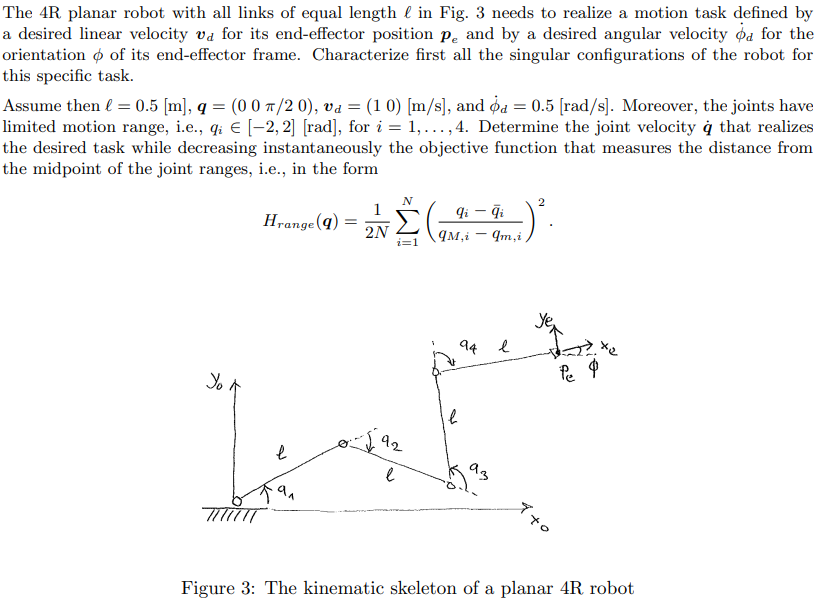

syms q1 q2 q3 q4 dq1 dq2 dq3 dq4 real
syms l1 l2 l3 l4 positive

p = [l1*cos(q1)+l2*cos(q1+q2)+l3*cos(q1+q2+q3)+l4*cos(q1+q2+q3+q4);
     l1*sin(q1)+l2*sin(q1+q2)+l3*sin(q1+q2+q3)+l4*sin(q1+q2+q3+q4);
               q1+q2+q3+q4];
J = jacobian(p,[q1,q2,q3,q4])

$$J = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1}-l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)-\sigma_{3} & -\sigma_{1}-l_{2}\,\sin\left(q_{1}+q_{2}\right)-\sigma_{3} & -\sigma_{1}-\sigma_{3} & -\sigma_{1}\\ \sigma_{2}+l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+\sigma_{4} & \sigma_{2}+l_{2}\,\cos\left(q_{1}+q_{2}\right)+\sigma_{4} & \sigma_{2}+\sigma_{4} & \sigma_{2}\\ 1 & 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=l_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{3}=l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

%det_J = simplify(det(J*J.'),steps=1000)

J_subs = eval(subs(J,[q1,q2,q3,q4,l1,l2,l3,l4],[0,0,pi/2,0,0.5,0.5,0.5,0.5]))

J_subs =    -1.0000   -1.0000   -1.0000   -0.5000
    1.0000    0.5000         0         0
    1.0000    1.0000    1.0000    1.0000


J_subs_pinv = pinv(J_subs)

J_subs_pinv =     0.3333    1.0000    0.1667
   -0.6667    0.0000   -0.3333
   -1.6667   -1.0000   -0.8333
    2.0000    0.0000    2.0000


product = J_subs_pinv*J_subs;
I = eye(4);
r_d_dot = [1; 0; 0.5;];
q_m = -2;
q_M = 2;
q_bar = (q_M + q_m)/2; 
range = q_M - q_m;    
q = [q1; q2; q3; q4];
H_q = (1/(2*length(q))) * sum(((q - q_bar)/range).^2);
diff_H_q = simplify(gradient(H_q, q));
q_dot = J_subs_pinv*r_d_dot + (I - product)*diff_H_q;
sol = eval(subs(q_dot,[q1,q2,q3,q4],[0,0,pi/2,0]))

sol =     0.4208
   -0.8415
   -2.0792
    3.0000
